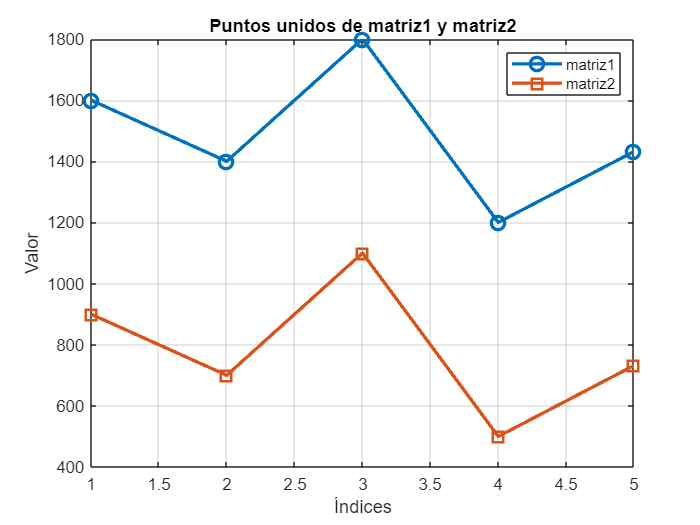

% Se toma la misma acción, solo difieren en distancia
matriz1 = [1600, 1400, 1800, 1200, 1432];
matriz2 = [900, 700, 1100, 500, 732];
% Crear un vector de índices para los datos
indices = 1:length(matriz1);
% Graficar los puntos unidos de matriz1
plot(indices, matriz1, '-o', 'LineWidth', 2, 'MarkerSize', 8);
hold on; % Mantener el gráfico actual para agregar más datos
% Graficar los puntos unidos de matriz2
plot(indices, matriz2, '-s', 'LineWidth', 2, 'MarkerSize', 8);
% Añadir etiquetas y título al gráfico
xlabel('Índices');
ylabel('Valor');
title('Puntos unidos de matriz1 y matriz2');
% Agregar leyenda
legend('matriz1', 'matriz2');
% Mostrar la cuadrícula
grid on;
% Soltar el gráfico actual
hold off;

% Calcular las pendientes de la primera matriz
pendiente_matriz1 = diff(matriz1);
disp(['Pendiente 1: ', num2str(pendiente_matriz1)]);

Pendiente 1: -200  400 -600  232


% Calcular las pendientes de la segunda matriz
pendiente_matriz2 = diff(matriz2);
disp(['Pendiente 2: ', num2str(pendiente_matriz2)]);

Pendiente 2: -200  400 -600  232


% Calcular la diferencia entre las pendientes
diferencia_pendientes = pendiente_matriz1 - pendiente_matriz2;
disp(['Diferencia entre las pendientes: ', num2str(diferencia_pendientes)]);

Diferencia entre las pendientes: 0  0  0  0


% Modificar la diferencia según los criterios
for i = 1:length(diferencia_pendientes)
    % Casos de valor -1
    if (pendiente_matriz1(i) > 0 && pendiente_matriz2(i) < 0) || ...
       (pendiente_matriz1(i) < 0 && pendiente_matriz2(i) > 0) || ...
       (pendiente_matriz1(i) > 0 && pendiente_matriz2(i) == 0) || ...
       (pendiente_matriz1(i) < 0 && pendiente_matriz2(i) == 0) || ...
       (pendiente_matriz1(i) == 0 && pendiente_matriz2(i) > 0) || ...
       (pendiente_matriz1(i) == 0 && pendiente_matriz2(i) < 0)
        diferencia_pendientes(i) = -1;
    % Casos de valor 1
    elseif (pendiente_matriz1(i) > 0 && pendiente_matriz2(i) > 0) || ...
           (pendiente_matriz1(i) < 0 && pendiente_matriz2(i) < 0) || ...
           (pendiente_matriz1(i) == 0 && pendiente_matriz2(i) == 0)
        diferencia_pendientes(i) = 1;
    end
end
% Mostrar la diferencia modificada
disp(['Diferencia entre las pendientes: ', num2str(diferencia_pendientes)]);

Diferencia entre las pendientes: 1  1  1  1


% Mostrar la recompensa
reward = sum(diferencia_pendientes);
disp(['LA RECOMPENSA ES: ', num2str(reward)]);

LA RECOMPENSA ES: 4


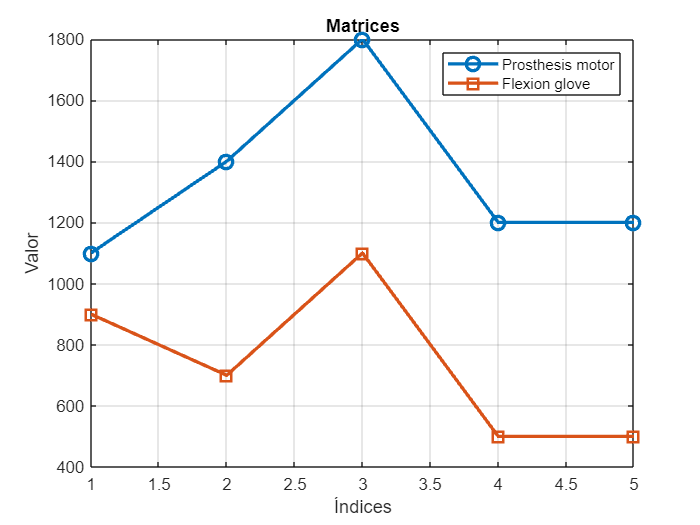

% Se toma la misma acción, solo difieren en distancia
matriz1 = [1100, 1400, 1800, 1200, 1200];
matriz2 = [900, 700, 1100, 500, 500];
% Crear un vector de índices para los datos
indices = 1:length(matriz1);
% Graficar los puntos unidos de matriz1
plot(indices, matriz1, '-o', 'LineWidth', 2, 'MarkerSize', 8);
hold on; % Mantener el gráfico actual para agregar más datos
% Graficar los puntos unidos de matriz2
plot(indices, matriz2, '-s', 'LineWidth', 2, 'MarkerSize', 8);
% Añadir etiquetas y título al gráfico
xlabel('Índices');
ylabel('Valor');
title('Matrices');
% Agregar leyenda
legend('Prosthesis motor', 'Flexion glove');
% Mostrar la cuadrícula
grid on;
% Soltar el gráfico actual
hold off;

% Calcular las pendientes de la primera matriz
pendiente_matriz1 = diff(matriz1);
disp(['Pendiente 1: ', num2str(pendiente_matriz1)]);

Pendiente 1: 300  400 -600    0


% Calcular las pendientes de la segunda matriz
pendiente_matriz2 = diff(matriz2);
disp(['Pendiente 2: ', num2str(pendiente_matriz2)]);

Pendiente 2: -200  400 -600    0


% Calcular la diferencia entre las pendientes
diferencia_pendientes = pendiente_matriz1 - pendiente_matriz2;
disp(['Diferencia entre las pendientes: ', num2str(diferencia_pendientes)]);

Diferencia entre las pendientes: 500    0    0    0


% Modificar la diferencia según los criterios
for i = 1:length(diferencia_pendientes)
    % Casos de valor -3
    if (pendiente_matriz1(i) > 0 && pendiente_matriz2(i) < 0) || ...
            (pendiente_matriz1(i) < 0 && pendiente_matriz2(i) > 0)
        diferencia_pendientes(i) = -3;
    % Casos de valor -2
    elseif(pendiente_matriz1(i) > 0 && pendiente_matriz2(i) == 0) || ...
            (pendiente_matriz1(i) < 0 && pendiente_matriz2(i) == 0) || ...
            (pendiente_matriz1(i) == 0 && pendiente_matriz2(i) > 0) || ...
            (pendiente_matriz1(i) == 0 && pendiente_matriz2(i) < 0)
        diferencia_pendientes(i) = -2;
        % Casos de valor 3
    elseif (pendiente_matriz1(i) > 0 && pendiente_matriz2(i) > 0) || ...
            (pendiente_matriz1(i) < 0 && pendiente_matriz2(i) < 0) || ...
            (pendiente_matriz1(i) == 0 && pendiente_matriz2(i) == 0)
        diferencia_pendientes(i) = 3;
    end
end
% Mostrar la diferencia modificada
disp(['Diferencia entre las pendientes: ', num2str(diferencia_pendientes)]);

Diferencia entre las pendientes: -3  3  3  3


% Mostrar la recompensa
reward = sum(diferencia_pendientes);
disp(['LA RECOMPENSA ES: ', num2str(reward)]);

LA RECOMPENSA ES: 6
